# Lab Assignment 3

First, we will see how eigenvalues and vectors can be used to find the principal components of a dataset. To understand PCA we need to understand the following statistical terms: *standard deviation, variance and covariance*.

- ***Sample Standard Deviation (SD)*** is a measure of the deviation from the mean of the data set to a point. The way to calculate it is to compute the squares of the distance from each data point to the mean of the set, add them all up, divide by *n-1*, and take the positive square root.


$$\mathit{\mathbf{s}}=\sqrt{\;\frac{\sum_{\mathit{\mathbf{i}}=1}^{\mathit{\mathbf{n}}} {\left({\mathit{\mathbf{X}}}_{\mathit{\mathbf{i}}\;} -\bar{\mathit{\mathbf{X}}} \right)}^2 }{\mathit{\mathbf{n}}-1}}$$


- ***Sample Variance (V): ***Variance is another measure of the spread of data in a data set. In fact it is the square of the standard deviation. The formula is this:

 
$${\mathit{\mathbf{s}}}^2 =$$
 
$$\frac{\sum_{\mathit{\mathbf{i}}=1}^{\mathit{\mathbf{n}}} {\left({\mathit{\mathbf{X}}}_{\mathit{\mathbf{i}}\;} -\bar{\mathit{\mathbf{X}}} \right)}^2 }{\mathit{\mathbf{n}}-1}$$


- ***Sample Covariance (C):*** Standard deviation and variance only operate on 1 dimension, so that you could only calculate the standard deviation for each dimension of the data set independently of the other dimensions. However, it is useful to have a similar measure to find out how much the dimensions vary from the mean with respect to each other. Covariance is such a measure. Covariance is always measured between 2 dimensions. If you calculate the covariance between one dimension and itself, you get the variance. So, if you had a 3-dimensional data set (*x,y,z*), then you could measure the covariance between the *x* and *y* dimensions, the *x *and *z* dimensions, and the *y* and *z* dimensions. Measuring the covariance between *x *and *x*, or *y *and *y*, or *z *and *z* would give you the variance of the *x*, *y* and *z* dimensions respectively.


$$\textrm{Cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}}\right)=$$
 
$$\frac{\sum_{\mathit{\mathbf{i}}=1}^{\mathit{\mathbf{n}}} {\left({\mathit{\mathbf{X}}}_{\mathit{\mathbf{i}}\;} -\bar{\mathit{\mathbf{X}}} \right)\left({\mathit{\mathbf{Y}}}_{\mathit{\mathbf{i}}} -\bar{\mathit{\mathbf{Y}}} \right)} }{\mathit{\mathbf{n}}-1}$$


- The covariance matrix shows the relationship between different features(i.e. columns) in the dataset. For a three dimentional dataset the covariance matrix would look something like this:


$$\textrm{Cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}},\mathit{\mathbf{z}}\right)\left\lbrack \begin{array}{c}
\textrm{cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{x}}\right)\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}}\right)\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{z}}\right)\\
\textrm{cov}\left(\mathit{\mathbf{y}},\mathit{\mathbf{x}}\right)\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{y}},\mathit{\mathbf{y}}\right)\;\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{y}},\mathit{\mathbf{z}}\right)\\
\textrm{cov}\left(\mathit{\mathbf{z}},\mathit{\mathbf{x}}\right)\;\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{z}},\mathit{\mathbf{y}}\right)\;\;\;\;\;\;\;\textrm{cov}\left(\mathit{\mathbf{z}},\mathit{\mathbf{z}}\right)
\end{array}\right\rbrack$$


- If the value is positive, then that indicates that both dimensions increase together. If the value is negative, then as one dimension increases, the other decreases. In the last case, if the covariance is zero, it indicates that the two dimensions are independent of each other.

## **Exercise 1: Eigenvalues and Eigenvectors**

- The eigenvalues and vectors describe the essense of how a matrix transforms a vector. To see the effect we can generate a set of vectors of unit length representing all directions:

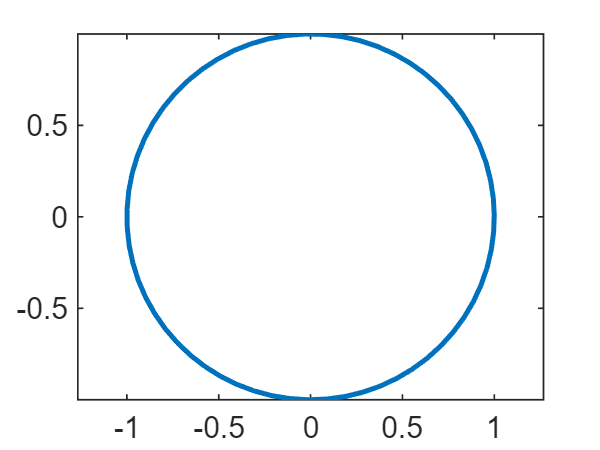

clear all;
t = 0:0.1:2*pi+0.1;
x = [cos(t); sin(t)];
plot(x(1,:),x(2,:),'LineWidth',1.5)
axis equal

- Let's Transform the vectors using some matrix A and see how it effects the vectors:

%wilder if smaller number
%1 stands for the range on the axises
A = [1 0.5
     0.5 1];
y = A*x

y =     1.0000    1.0449    1.0794    1.1031    1.1158    1.1173    1.1077    1.0870    1.0554    1.0133    0.9610    0.8992    0.8284    0.7493    0.6627    0.5695    0.4706    0.3670    0.2597    0.1499    0.0385   -0.0732   -0.1843   -0.2934   -0.3997   -0.5019   -0.5991   -0.6904   -0.7747   -0.8513   -0.9194   -0.9783   -1.0275   -1.0664   -1.0946   -1.1118   -1.1180   -1.1130   -1.0969   -1.0698   -1.0320   -0.9840   -0.9260   -0.8589   -0.7831   -0.6996   -0.6090   -0.5124   -0.4106   -0.3047
    0.5000    0.5973    0.6887    0.7732    0.8499    0.9182    0.9773    1.0266    1.0657    1.0941    1.1116    1.1180    1.1132    1.0973    1.0704    1.0329    0.9850    0.9272    0.8602    0.7847    0.7012    0.6108    0.5142    0.4126    0.3068    0.1979    0.0871   -0.0247   -0.1361   -0.2462   -0.3539   -0.4580   -0.5575   -0.6515   -0.7389   -0.8190   -0.8909   -0.9539   -1.0073   -1.0507   -1.0836   -1.1057   -1.1167   -1.1166   -1.1053   -1.0829   -1.0498   -1.0061   -0.9524   -0

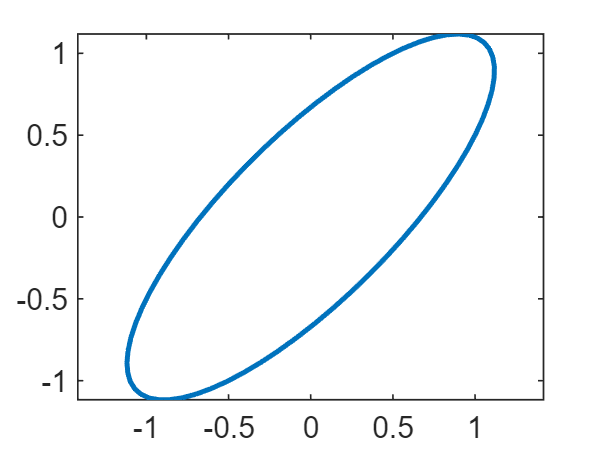

plot(y(1,:),y(2,:),'LineWidth',1.5)
axis equal

- Using the eigenvectors and values we can compactly capture the effect of the matrix, and draw the transform. The transform here means the direction in which the vectors were affected the most. You can plot the major and minor axis of this ellipse to visualize the magnitude of change.

[X,D] = eig(A)

X =    -0.7071    0.7071
    0.7071    0.7071


D =     0.5000         0
         0    1.5000


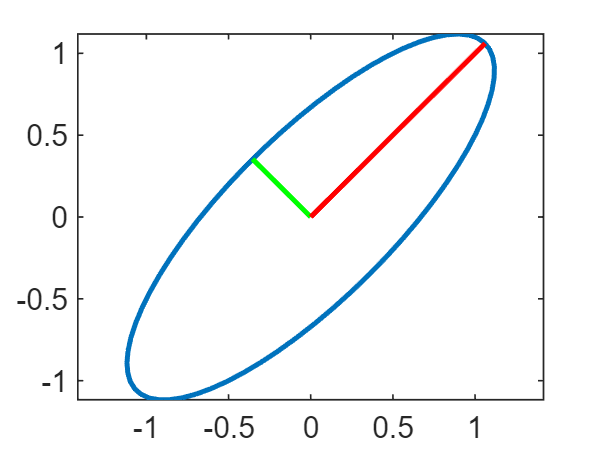

plot(y(1,:),y(2,:),'LineWidth',1.5)
axis equal
hold on
plot(D(1,1)*[0 X(1,1)],D(1,1)*[0 X(2,1)],'g','LineWidth',1.5)
plot(D(2,2)*[0 X(1,2)],D(2,2)*[0 X(2,2)],'r','LineWidth',1.5)
hold off

- Try a few of these transforms on your own (no need to turn in), to get an idea of the effect of different matrices. Remember that (symmetric) positive definite matrices will give you real orthonormal eigenvectors. Unsymmetric matrices may give complex results. To think about: In the above example we only rotated and scaled. More generally we can also add translation $\mathit{\mathbf{y}}=\mathit{\mathbf{A}}\ldotp \mathit{\mathbf{x}}+\mathit{\mathbf{t}}$. You might try on your own to make a routine which can plot any ellipse given its parametric form (as in Heath Computer problem 3.5). A more common problem in practice is that we have data that we want to somehow characterize. The data may have significant variation along some axis and less along others. A common model is that of a Gaussian distribution. If there is little variation along a particular axis, that dimension could be omitted altogether. 

%You can create your own Gaussian Distribution using the following code:
% Gaussian distr, Box-Mueller method

n = 400

n = 400

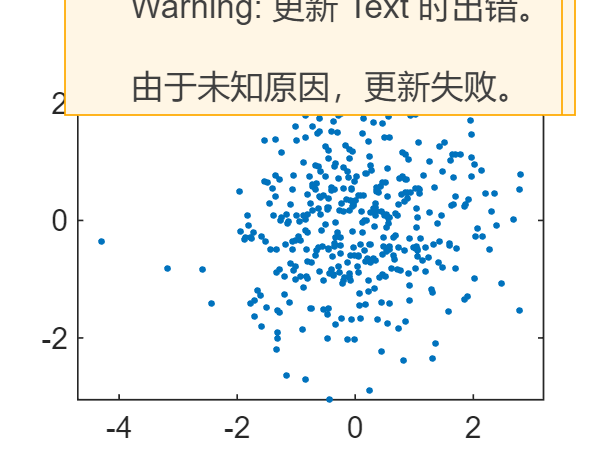

U = rand(2,n);
v = 2*pi*U(2,:);
G = ones(2,1)*sqrt(-2.*log(U(1,:))).*[cos(v);sin(v)];

plot(G(1,:),G(2,:),'.')
axis equal

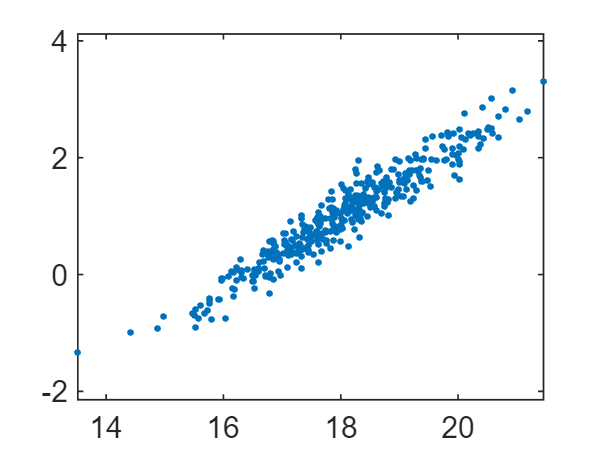


% Transform
A = [1 .5
     .5 .5];
t = [18; 1];
Y = A*G+t*ones(1,n);
plot(Y(1,:),Y(2,:),'.')

axis equal


[X,D] = eig(A)

X =     0.5257   -0.8507
   -0.8507   -0.5257


D =     0.1910         0
         0    1.3090


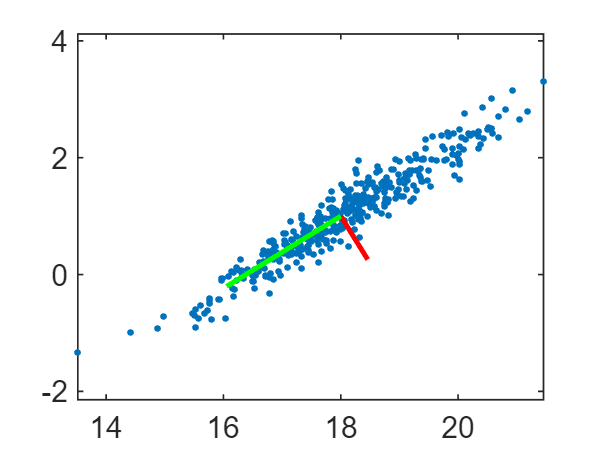

D=sqrt(D);
plot(Y(1,:),Y(2,:),'.')
axis equal
hold on
%2*D*[0 X(1,1)]+t(1)
plot(2*D(1,1)*[0 X(1,1)]+18,2*D(1,1)*[0 X(2,1)]+1,'r','LineWidth',1.5)
plot(2*D(2,2)*[0 X(1,2)]+18,2*D(2,2)*[0 X(2,2)]+1,'g','LineWidth',1.5)
hold off

## Principal Componet Analysis (PCA)

Principal components are the orthogonal vectors which correspond to highest variance of the data. Eigenvalues are the variances in the direction of the corresponding eigenvector.

When using PCA we need to standardize the data by transforming it to having mean = 0. This is important because in PCA we will be looking at how different features contribute to the spread of the data. Therefore, different features must be comparable in terms of scale. Here we show how to standardize the data:


$$\textrm{For}\;\textrm{any}\;\textrm{matrix}\;{\mathit{\mathbf{A}}}_{\mathit{\mathbf{m}}\times \mathit{\mathbf{n}}}$$



$${\mathit{\mathbf{A}}}_{\textrm{std}} =\frac{\left(\mathit{\mathbf{A}}-\bar{\mathit{\mathbf{A}}} \right)}{s}$$
        


$$\textrm{Cov}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}}\right)={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}$$


Here, the eigenvectors of this covariance matrix are the principal components. **Can you explain why (based on the definition of Covariance stated above)?**

- In this exercise you will use PCA as described in the [this document](https://drive.google.com/file/d/1WXEtpBKHu_ZzSUMMrmejGIsPjVALYaeI/view?usp=sharing) and below. The purpose is to recover the main axes of the distribution and plot the axes with length (2*sqrt of eigenvalues). You can plot the axes as in the Gaussian example above, or plot an ellipse corresponding to the axes.

- Three data sets Y1, Y2 and Y3 are provided in [EllipsePoints.mat](https://drive.google.com/file/d/1WdXYGlvfQ-c19tOv3efVAQ9vzqNc7Ofy/view?usp=sharing). Show how to find the major and minor axes of those.

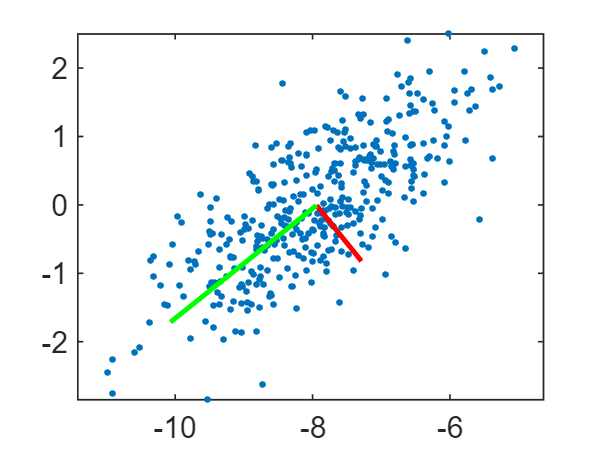

%%%%            Enter your code here        %%%%
%Add relevant comments and answers to the questions asked

%The covariance matrix summarizes the variability of a dataset.
%The eigenvector of the covariance matrix is equivalent to the direction 
%which captures most of the variance in the data. This is exactally what we
%want for principal components, which represent the part where data is most
%uncorrelated. PCA would convert the correlated data intouncorrelated data 
%by doing orthogonal transformation. Besides, the eigenvectors of distinct 
% eigenvalues are orthogonal.

clear all;
load EllipsePoints.mat

[V1,D1,t1] = PCA(Y1);
plot(Y1(1,:),Y1(2,:),'.')
axis equal
hold on
plot([t1(1) 2*sqrt(D1(1,1))*[0 V1(1,1)]+t1(1)], [t1(2) 2*sqrt(D1(1,1))*[0 V1(2,1)]+t1(2)],'r','LineWidth',1.5)
plot([t1(1) 2*sqrt(D1(2,2))*[0 V1(1,2)]+t1(1)], [t1(2) 2*sqrt(D1(2,2))*[0 V1(2,2)]+t1(2)],'g','LineWidth',1.5)
axis equal
hold off

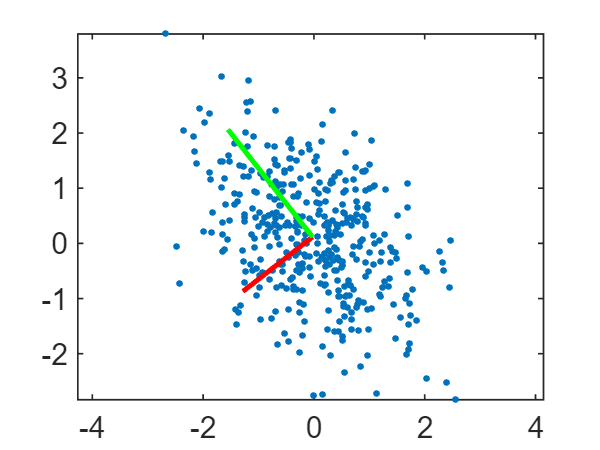


[V2,D2,t2] = PCA(Y2);
plot(Y2(1,:),Y2(2,:),'.')
axis equal
hold on
plot([t2(1) 2*sqrt(D2(1,1))*[0 V2(1,1)]+t2(1)], [t2(2) 2*sqrt(D2(1,1))*[0 V2(2,1)]+t2(2)],'r','LineWidth',1.5)
plot([t2(1) 2*sqrt(D2(2,2))*[0 V2(1,2)]+t2(1)], [t2(2) 2*sqrt(D2(2,2))*[0 V2(2,2)]+t2(2)],'g','LineWidth',1.5)
axis equal
hold off

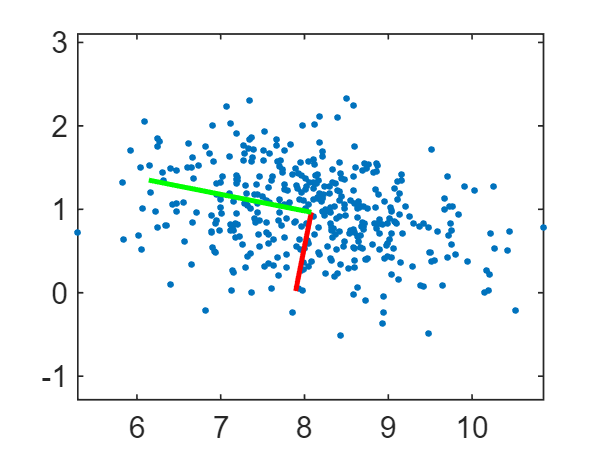


[V3,D3,t3] = PCA(Y3);
plot(Y3(1,:),Y3(2,:),'.')
axis equal
hold on
plot([t3(1) 2*sqrt(D3(1,1))*[0 V3(1,1)]+t3(1)], [t3(2) 2*sqrt(D3(1,1))*[0 V3(2,1)]+t3(2)],'r','LineWidth',1.5)
plot([t3(1) 2*sqrt(D3(2,2))*[0 V3(1,2)]+t3(1)], [t3(2) 2*sqrt(D3(2,2))*[0 V3(2,2)]+t3(2)],'g','LineWidth',1.5)
axis equal
hold off


%variance=0 if all variables are the same
%%%%            End             %%%%

## **Exercise 2: A moving wave image**

The effect of image motion can be obtained by modulating a sin/cos basis. Considering the following formula:


$$\;\sin \left(\textrm{ax}+\textrm{bt}\right)=\sin \left(\textrm{ax}\right)\cos \left(\textrm{bt}\right)+\cos \left(\textrm{ax}\right)\sin \left(\textrm{bt}\right)$$


where a and b are constants, x is the spatial variable and t is time. We can interpret the above formula as the modulation of a sin and cos spatial basis with time varying coefficients - cos(bt), sin(bt). The example can be extended in 2D. Download the [sincos_basis.mat](https://drive.google.com/file/d/1WfeNzDTpaUEz6KQE2kgG0S5bFQiLck5l/view?usp=sharing) data. B contains the sin/cos image basis (as columns) and Y is an example set of temporal modulation coefficients (each set of coefficients is a column, hence Y(:,1) are the coefficients for time 1, Y(:,2) for time 2 etc.). Show the modulated images on the screen in quick succession resulting from the different coefficients in Y. You can use imshow, then drawnow to force immediate rendering to the screen.

You can use the function [renderim.m](https://drive.google.com/file/d/1WhsMAo1TSdSbsPx-a5gpk-TBk0KX_CCZ/view?usp=sharing) Ii = renderim(Y(:,i),B,imsize); imshow(Ii,[]); drawnow; pause(0.1);

**Why do you see the pattern moving even though it only has 1 frame? **

%because reshape is undergoing, which creates the motion
load sincos_basis.mat;
figure('visible','on')
for i=1:64
Ii=renderim(Y(:,i),B,imsize);
imshow(Ii,[]);
drawnow;
pause(0.01);
end

- Construct a similar basis that has twice the frequency of the given one and show the effect of motion through modulation.

- **What is the effect of changing b ?**

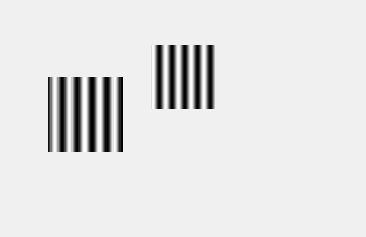

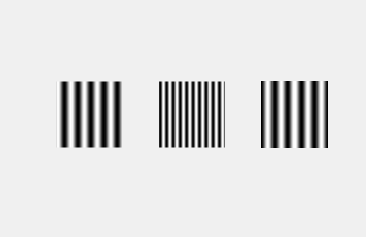

%%%%            Enter your code here            %%%%
%Add relevant comments and answers to the questions asked

%the first picture is the original one.
%the second one changes matrix B
%the third on changes b in matrix Y

clear all;

load sincos_basis.mat
%sin(2x)=2sinx.cosx
%cos(2x)=1-2sin^2(x)
%[cos(2x)   [1-2sin^2(x)
% sin(2x)]=  2sin(x).cos(x)]

%add 2times b inside Y. as stated above
%cos(2x)                                    sin(2x)
newY=[ones(1,size(Y,2))-2*(Y(2,:).*Y(2,:)); 2*Y(1,:).*Y(2,:)];
%B contains the sin/cos basis as coloums
%sin(2x)               %cos(2x)     
newB=[2*B(:,1).*B(:,2) ones(size(B,1),1)-2*B(:,1).*B(:,1)];
for i = 1:64
    
    Ii = renderim(Y(:,i),B,imsize); 
    subplot(1,3,1);
    imshow(Ii,[]); 
    drawnow; 
    pause(0.1);
    
    %changing matrix B decreases the frequency of motion, 
    %lines are thinner
    Ii = renderim(Y(:,i),newB,imsize); 
    subplot(1,3,2);
    imshow(Ii,[]); 
    drawnow; 
    pause(0.1);

    % changing b increases the speed of the motion
    Ii = renderim(newY(:,i),B,imsize); 
    subplot(1,3,3);
    imshow(Ii,[]); 
    drawnow; 
    pause(0.1);
    
end

%%%%            End             %%%%

## **Exercise 3: Small image motion**

Consider an image $\mathit{\mathbf{I}}=\left(\mathit{\mathbf{u}},\mathit{\mathbf{v}}\right)$. We study the effect of a small shift (horizontal and vertical) using Taylor expansion:


$$\mathit{\mathbf{I}}\left(\mathit{\mathbf{u}}+\textrm{du},\mathit{\mathbf{v}}+\textrm{dv}\right)=\mathit{\mathbf{I}}\left(\mathit{\mathbf{u}},\mathit{\mathbf{v}}\right)+\left\lbrack \textrm{Ix}\left(\mathit{\mathbf{u}},\mathit{\mathbf{v}}\right)\textrm{Iy}\left(\mathit{\mathbf{u}},\mathit{\mathbf{v}}\right)\right\rbrack \left\lbrack \textrm{du}\;\textrm{dv}\right\rbrack \prime +\textrm{hot}$$


$\textrm{GI}=\left\lbrack \textrm{Ix}\;\textrm{Iy}\right\rbrack$ represents the image gradient. Again we can interpret the above formula using image modulation. In this case the basis B is formed by $\left\lbrack \mathit{\mathbf{I}},\;\textrm{Ix},\;\textrm{Iy}\right\rbrack$ and the coefficients are of the form $\left\lbrack 1\;\textrm{du}\;\textrm{dv}\right\rbrack$. The effect of the modulation is a small image shift. In the below we compute the derivative by taking differences in spatial coordinates. It is also possible to use a time series of images, akin to this example of a [bus](https://docs.google.com/document/d/19ONkicvWPNBcW6BZTkp7PhyiQPvqL4zpB57f1JBw9co/edit?usp=sharing).

Download the [immotion_basis.mat](https://drive.google.com/file/d/1WqAEQECjX35QumdcduaR-V7nv_BW5XYZ/view?usp=sharing) data. The data is in the same format as before. Visualize the motions produced by the given coefficients the same way as for the example above. (You can slow down the rendering speed to see the effect better by using a more finely spaced set of t-values, e.g. -3:0.2:3, appropriatetely inserted into the Y matrix of coefficients.

Repeat the procedure for another image of your choice. To calculate the image gradient (derivatives) use the Matlab function 'gradient'. Study the effect of changing the magnitudes of the coefficients in Y. What happens if you pick larger Y values (e.g. 5:10)? **Why? What type of image does this procedure work best for? Explain appealing to the Taylor expansion what happens when it doesn't work.**

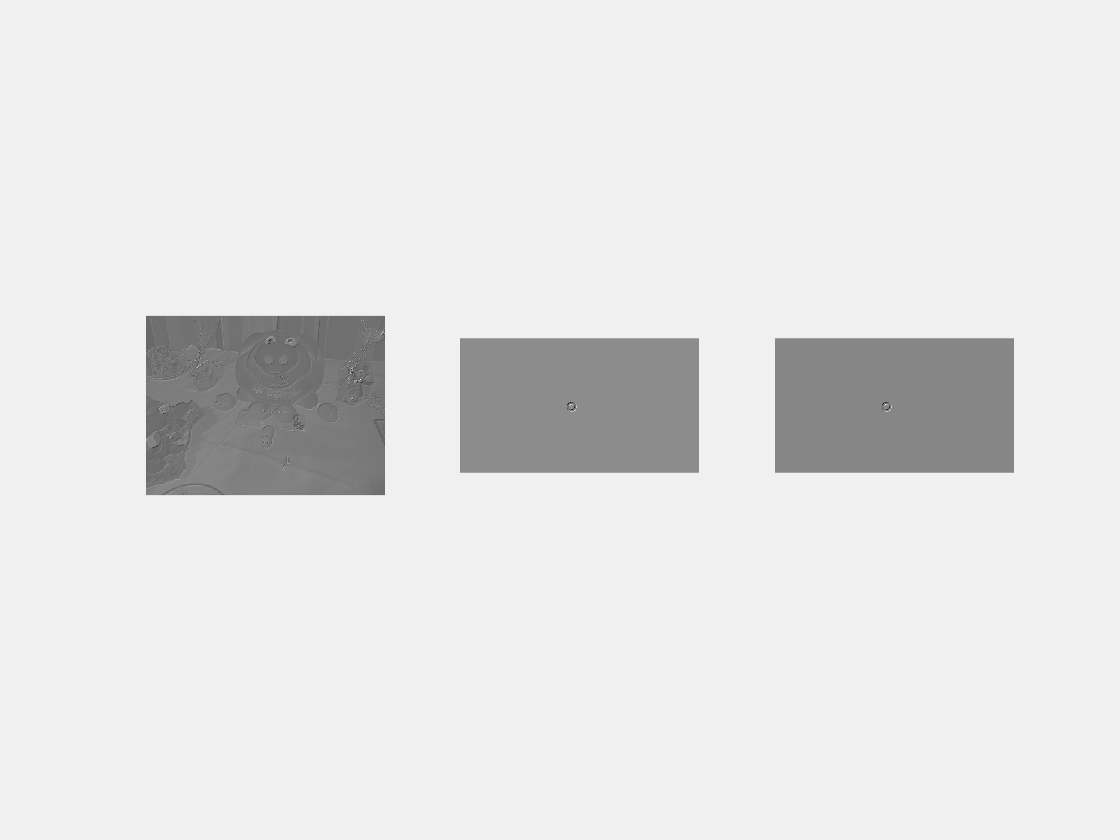

%%%%            Enter your code here            %%%%
%Add relevant comments and answers to the questions asked

%after picking larger Y, the motion became smaller and not obvious.
%The images with many patterns are more suitable for this procedure.
%Based on the taylor expansion, where we calculated the gradient of a
%picture, and since image gradient is a directional change in the intensity 
% or color in an image, which means if the whole picture is just all black,
%then there is not much difference in the image's gradient. Therefore, this
%type of proceduce is not working for the images with many blanks on
%them.(this can be seen by loading image '1.jpg')

%Suppose an image is made up with many small elements.
%with larger Y, when doing the reshape(renderim), it will create large gap
%between each element, which will create small motion for the procedure.
close all;
clear all;

load immotion_basis.mat

figure('visible','on')
for i=1:13
    Ii = renderim(Y(:,i),B,imsize); 
    subplot(1,3,1);
    imshow(Ii,[]);
    pause(0.5);
end


I=imread('1.jpg');
I = im2gray(I);
I = im2double(I);%to double precision
[Ix,Iy]=gradient(I);
newB =[I(:) Ix(:) Iy(:)];

for i=1:13
    Ii = renderim(Y(:,i),newB, size(I)); 
    subplot(1,3,2);
    imshow(Ii,[]);
    drawnow; 
    pause(0.5);
end

%add 5 to row 2 and 3
largeY=[1 1 1 1 1 1 1 1 1 1 1 1 1;
        5 6 7 8 9 5 5 5 5 6 7 8 9;
        5 5 5 5 5 6 7 8 9 6 7 8 9];

for i=1:13
    Ii = renderim(largeY(:,i), newB, size(I)); 
    imshow(Ii,[]);
    subplot(1,3,3);
    drawnow; 
    pause(0.5);
end


%%%%            End             %%%%

function [V,D,t] = PCA(Y)
%the mean of each row size: Y*1
%suppose Y is 3x4 matrix, then t is 3*1 matrix
    t = mean(Y,2);%y bar
    %y_approx is 3*4
    %size 1*second dim of sizeY
    A_sd = (Y - t*ones(1,size(Y,2))); 
    C = (A_sd* (A_sd'))/size(Y,2); %A^T * A
    [V, D] = eig(C);
end